# SC42025 Filtering & Identification

**PRACTICAL ASSIGNMENT II**

**Instructions: Fill in the live script with your code and answers. Then export the live script as a pdf (in the 'Live Editor tab', click on the arrow under 'Save' and then 'Export to pdf'). Hand in one report per group before the deadline.**

**DEADLINE**: 

## Introduction

In this practical assignment you will use your model-estimation code from Homework Assignments 3 & 4  to identify an unknown system by going through the system identification cycle. For this, you need the file `exciteSystem.p`, which you can find on Brightspace. Note that this file requires the `System Identification Toolbox.(and the Statistics and Machine Learning toolbox as well) `You may consider this file as an **unknown black box system**. You can provide an input sequence and a sampling frequency to this system and it will return a corresponding output sequence at the specified sampling frequency.

The file is used by adding it to your path in MATLAB and calling the function

`y = exciteSystem(STUDENTID,u,fs)`

Here, `y` is the output sequence $$y_k$$ of the to be identified system, `STUDENTID` is the **lowest-valued** student-id of the students in the group, `u` is the provided input sequence $u_k$, and` fs` is the sampling frequency. 

The system is inherently simulated in discrete time, so there is **no need for you to apply a band-pass filter to prevent anti-aliasing**, as you need to do for analog systems that have been sampled digitally. Your objective is to identify a model for this black box system. Try to determine a model that performs well on both your identification as your validation data set in terms of simulation.

It can be expected that non-Gaussian sensor noise (noise spikes) will be present in the output. These spikes need to be removed from the data before identifying the system. 

Your system may also contain a time delay. This should also be taken into account before using your identification code.

To complete this assignment, we expect you to go trough the identification cycle, see the figure below, as many times as needed.

*Throughout this practical assignment, remember that the identification cycle is an iterative process and you typically need more than one iteration. Limit your report to the final iteration.*

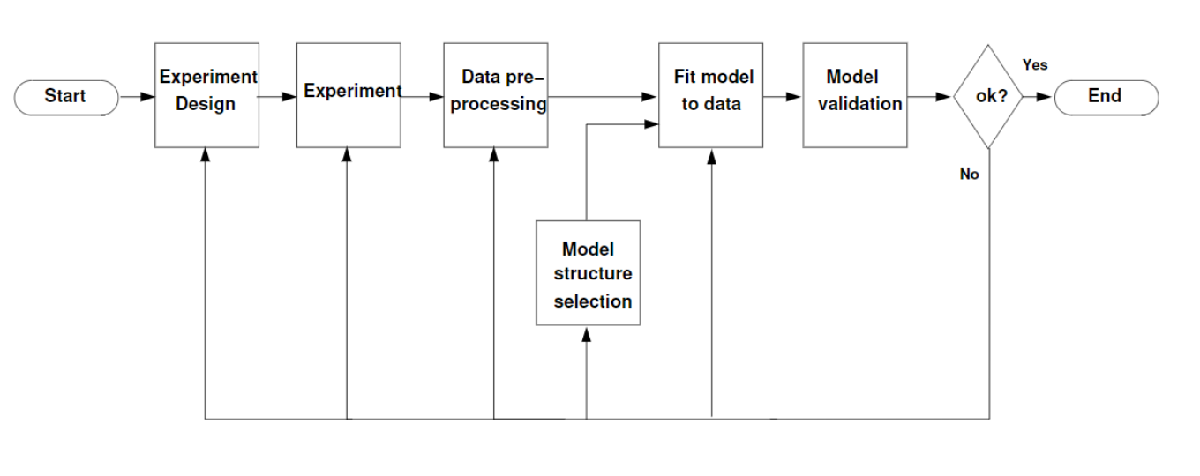

## Part 0: Setup

Please insert your names and student numbers below.

Name:

Student Number:

Name: 

Student Number:

% Clear workspace
clc; close all;
clearvars;

% Insert the lowest-valued student-id of the students in the group;
STUDENTID = 5476747;

## Part 1: Experiment Design and Data Pre-Processing

The first steps of the identification cycle are to design your experiment and pre-process the input and output data. In this exercise, use the `exciteSystem` function to

Determine a suitable sampling frequency and motivate your answer.

*Answer**:*

*The statistics and machine learning toolbox is also needed for exciteSystem to run, not just the system identification toolbox. *

*First a suitably high input size had to be found, so sensor noise plays little role in identification. Then the open loop rise time was measured at 4.9439 seconds in a simulation with no spike during the corresponding part in the transients. Taking the sampling the sampling time as 10 times that gives 0.494 seconds. *

% some stuff
%% data generation
Nt = 150;
step_inputs = ones(Nt, 1)*10000;
dt = 0.494;
% dt = 0.5;
t = 0:Nt-1;
t = t*dt

t =          0    0.4940    0.9880    1.4820    1.9760    2.4700    2.9640    3.4580    3.9520    4.4460    4.9400    5.4340    5.9280    6.4220    6.9160    7.4100    7.9040    8.3980    8.8920    9.3860    9.8800   10.3740   10.8680   11.3620   11.8560   12.3500   12.8440   13.3380   13.8320   14.3260   14.8200   15.3140   15.8080   16.3020   16.7960   17.2900   17.7840   18.2780   18.7720   19.2660   19.7600   20.2540   20.7480   21.2420   21.7360   22.2300   22.7240   23.2180   23.7120   24.2060



system = @(u) exciteSystem(STUDENTID, u, 1/dt);
resp = system(step_inputs);

plot(t, resp)
% ylim([-20, 500000])
% xlim([20, 30])

area_of_interest = [15, 30];
condition = (t > area_of_interest(1) & t< area_of_interest(2));

indices = find(condition);
t_interest = t(condition);
resp_interest = resp(indices);
stepinfo(resp_interest, t_interest)

ans = struct with fields:
         RiseTime: 4.9083
    TransientTime: 26.1807
     SettlingTime: 29.3108
      SettlingMin: 3.2859e+05
      SettlingMax: 3.7315e+05
        Overshoot: 7.7488
       Undershoot: 622.5652
             Peak: 2.1560e+06
         PeakTime: 24.2060


plot(t_interest, resp_interest)

Design a persistingly exciting input signal. Show how you determined the order of persistency of excitation.  Furthermore, you are **not allowed** to use a white-noise sequence as an input signal, as this is often not possible in the real-world.

*Answer**:*

*The order of a persistently exciting signal is the highest *`s`* for which an N exists, for which the following statement holds:*


$$\Phi_N = \pmatrix{u_0 & u_1 & \dots & u_{s-1} \cr
u_1 & u_2 & \dots & u_{s} \cr
    \vdots & \vdots & & \vdots \cr
    u_{N-s+1} & u_{N-s+2} & \dots & u_{N-1} }$$


It can easily be seen that this is a symmetric matrix and the rank of a symmetric matrix will be the number of nonzer eigenvalues. Therefore a persistently exciting signal of rank s will consist of `s` impulses/short pulses, each having `s+1` steps between them, giving a total length of  `s^2.`

%% signal generation
signal_order = 4;
signal = diag(1:signal_order);


Motivate how you identify and remove spike noise from your data.*You may use the Matlab function *`interp1`* to do the interpolation. *Plot a figure of the output signal before and after spike removal.

*Answer**:*

*Data points are classified as outliers if the data value is at least twice the expected steady state output of the system for the past 4 inputs, which is roughly 35, reading form the graphs. *

cleaned = clean_resp(step_inputs, resp)

cleaned = 1.0e+05 *

    0.0000    0.0000    0.0001    0.0000    0.0000    0.0002    0.0001    0.0002    0.0001   -0.0000   -0.0000   -0.0000   -0.0001    0.0000    0.0001    0.0002   -0.0000   -0.0000   -0.0001   -0.0001   -0.0000   -0.0001   -0.0000    0.0000    0.0002    0.0001    0.0000   -0.0000    0.0001    0.0000    0.0001    0.0001    0.0001    0.0002   -0.0000    0.0001    0.0000    0.0001   -0.0000   -0.0002   -0.0001    0.0000    0.0000    0.1255    0.6628    1.2788    1.8482    2.2758    2.5240    2.6246


plot(cleaned)

Determine any time-delays of your system. Correct the input and output data to account for the determined time-delay by introducing an appropriate time-shift.

*Answer**:*

* Zooming in on the graph the delay appears after the 51st timestep, so the delay is roughly 20.5 s.*

%YOUR CODE HERE
area_of_interest = [20, 22];
condition = (t > area_of_interest(1) & t< area_of_interest(2));

indices = find(condition);
t_interest = t(condition);
resp_interest = resp(indices);
plot(t_interest, resp_interest)

sample_delay = 41;
u = [zeros(sample_delay, 1); step_inputs(1:end-sample_delay)];

hold on
plot(t, cleaned);
plot(t, u);
hold off

Remove the DC offset from the output (if any).

*Answer**:*

*The dc offset will be the average of the steady values of a negative and a posititve step response. Noise does play a factor here, so the average of the last few points of the response are taken as the steady state value. After a couple of reruns this stays around +7. This is subtracted to get a balanced response.*

%YOUR CODE HERE
[resp_pos, u_pos, t_pos] = get_clean_response(10000, 250, STUDENTID);
[resp_neg, u_neg, t_neg] = get_clean_response(-10000, 250, STUDENTID);

figure;
hold on
plot(t_pos, resp_pos);
plot(t_neg, resp_neg);
hold off

offset = mean(mean(resp_pos(end-25:end)) + mean(resp_neg(end-25:end)))

offset = NaN

Determine whether your system is (approximately) linear by means of an experiment. Plot a figure of the experiment that you used and use this figure to motivate your conclusions.

*Answer**:*

*Supplying the multiple of an input, the output should also increase by the same factor, and this can be observed in the plots attached below. The ratios of the responses correspond to the ratios of the inputs, which means the system is linear. *

%YOUR CODE HERE
[resp_small, u_small, t_small] = get_clean_balanced_dc_free_step(1000, 250, STUDENTID);
[resp_med, u_med, t_med] = get_clean_balanced_dc_free_step(2000, 250, STUDENTID);
[resp_large, u_large, t_large] = get_clean_balanced_dc_free_step(3000, 250, STUDENTID);
figure;
hold on
plot(t_small, resp_small);
plot(t_med, resp_med);
plot(t_large, resp_large);
hold off
mean(resp_large./resp_small)

ans = NaN

mean(resp_med./resp_small)

ans = NaN

Generate output data that you will use for identification using your persistently exciting input signal. Also generate new data that you will use for validation.

*Answer**:*

*5 sets of signals are generated, each 100 long, with the input values rearranged for each of them. Each of them are of order 10.*

signal_order = 10;
series1 = 1:1:signal_order;
series2 = signal_order:-1:1;
series3 = [1:2:signal_order; 2:2:signal_order];
series4 = (1:1:signal_order)/2;
series4(2:2:signal_order) = (signal_order:-2:2)/2 + signal_order/2;
series5 = series4(signal_order:-1:1);


signal1 = create_signal(series1)*1000;
signal2 = create_signal(series2)*1000;
signal3 = create_signal(series3)*1000;
signal4 = create_signal(series4)*1000;
signal5 = create_signal(series5)*1000;

[data1, inputs1, time1] = get_excited_response(signal1, STUDENTID);
[data2, inputs2, time2] = get_excited_response(signal2, STUDENTID);
[data3, inputs3, time3] = get_excited_response(signal3, STUDENTID);
[data4, inputs4, time4] = get_excited_response(signal4, STUDENTID);
[data5, inputs5, time5] = get_excited_response(repelem(signal5, 4), STUDENTID);

inputs5 

inputs5 =         6000
        6000
        6000
        6000
           0
           0
           0
           0
           0
           0


% figure;
% plot(time1, data1)

## Part 2: Identification

You will now identify your system using the data that you generated in Part 1. Here, we highly recommend you to use your code from Homework Assignments 3 & 4. It is however **not allowed** to use tools from the `System Identification Toolbox` to identify your system.

Determine the model order. Plot the singular values using the `semilogy` command and motivate your choice of order.

*Answer**:*

%YOUR CODE HERE


Identify the model. You are free to choose the identification method.

*Answer**:*

%YOUR CODE HERE

## Part 3: Validation

The final step of the system identification cycle is to validate your model. In this part you will validate your identified model using validation data that was **not** used during identification. 

Compare and discuss the VAF for the identification data with the VAF for the validation data.

*Answer**:*

%YOUR CODE HERE

Determine and discuss the auto-correlation of the residuals.

*Answer**:*

%YOUR CODE HERE

Determine and discuss the cross-correlation between the residuals and the inputs.

*Answer**:*

%YOUR CODE HERE

**Is your model OK? If not, return to Part 1 and Part 2 for the next iteration. **

## Functions

Implement your functions in this section

### Prediction Error Methods

Implement your PEM functions below 

%YOUR CODE HERE
function [A,B,C,D,x0]=pomoesp(u,y,s)
% Instructions:
% Implement your subspace ID method here.
% Use the following function inputs and outputs.

% Function INPUT 
% u         system input (matrix of size N x m)
% y         system output (matrix of size N x l)
% s         block size (scalar)
%
% Function OUTPUT
% A         System matrix A (matrix of size n x n)
% B         System matrix B (matrix of size n x m)
% C         System matrix C (matrix of size l x n)
% D         System matrix D (matrix of size l x m)
% x0        Initial state (vector of size n x one)

% YOUR CODE HERE   

N = length(u);
n = 3;

U_hankel = hankel(u(1:2*s),u(2*s:N));
Y_hankel = hankel(y(1:2*s),y(2*s:N));

L = qr([U_hankel(s+1:2*s,:);U_hankel(1:s,:);Y_hankel]',0)';
L_32 = L(3*s+1:4*s,s+1:3*s);

plot(svd(L_32))

l = 1;
[U, ~, ~] = svd(L_32,"econ");

C = U(1:l,1:n);
A = U(1:(s-1)*l,1:n)\U(l+1:end,1:n);

m = 1;
O = zeros(l*N,n);
P = zeros(l*N,n*m);

for k=1:N
    O(k,:) = C*A^(k-1);
    if k < N
        for j = 1:k
            P(k+1,:) = P(k+1,:)+C*A^(k-j)*u(j);
        end
    end
end

Phi = [O, P, u];
x0BD=Phi\y;
x0=x0BD(1:n);
B=x0BD(n+1:2*n);
D = x0BD(2*n+1);
end

### Subspace ID Methods

Implement your Subspace ID functions below 

%YOUR CODE HERE

#### Other functions

function[resp_clean] = clean_resp(u, resp)
    len = length(u);
    u_max = u*0;
    u_max(1) = u(1);
    for i = 2:len
        if abs(u(i)) > u_max(i)
            u_max(i) = abs(u(i));
        else
            u_max(i) = u_max(i-1);
        end
    end
    u = u_max;
    expectation = u_max;
    condition = (resp < abs(expectation) * 35 * 1.3 & resp > abs(expectation) * -35 * 1.3);
    % condition2 = [true; ((resp(2:end) - resp(1:end-1)) > resp(2:end)* 35 * 2)];
    % condition = condition & condition2;
    inliers = [];
    i = 2;
    while i <= len
        i0 = i-1;
        while (abs((resp(i) - resp(i-1)) / resp(i-1)) < 0.005)
            i = i+1;
            if i == len
                break;
            end
        end
        if (i-i0) < 4 || (i-i0) > 6
            inliers = [inliers, i0:i-1];
        end

        i = i+1;
    end
    resp_clean = interp1(inliers, resp(inliers), 1:len);
    u = u(inliers);
    % resp_clean = medfilt1(resp, 13);
end

function[cleaned, u_shifted, t] = get_clean_response(magnitude, Nt, STUDENTID)
    step_inputs = ones(Nt, 1)*magnitude;
    dt = 0.494;
    t = 0:1:Nt-1;
    t = t*dt;
    
    system = @(u) exciteSystem(STUDENTID, u, 1/dt);
    resp = system(step_inputs); 

    cleaned = clean_resp(step_inputs, resp);

    sample_delay = 41;
    % u_shifted = [zeros(sample_delay, 1); step_inputs(1:end-sample_delay)];
    u_shifted = step_inputs(1:end-sample_delay);
    cleaned = cleaned(sample_delay:end);
    t = t(sample_delay:end);
end

function[cleaned, u_shifted, t] = get_clean_balanced_dc_free_step(magnitude, Nt, STUDENTID)
    [cleaned, u_shifted, t] = get_clean_response(magnitude, Nt, STUDENTID);
    cleaned = cleaned - 7;
end

function[cleaned, u_shifted, t] = get_excited_response(inputs, STUDENTID)
    sample_delay = 41;    
    Nt = length(inputs);
    dt = 0.494;
    t = 0:Nt+sample_delay-1;
    t = t*dt;
   
    inputs = [inputs; zeros(sample_delay, 1)];
    resp = exciteSystem(STUDENTID, inputs, 1/dt);
    

    cleaned = clean_resp(inputs, resp);

    % u_shifted = [zeros(sample_delay, 1); step_inputs(1:end-sample_delay)];
    u_shifted = inputs(1:end-sample_delay-1);
    cleaned = cleaned(sample_delay+1:end);
    t = t(sample_delay+1:end);
    cleaned = cleaned - 7;
end

function[series] = create_signal(values)
    series =  diag(values);
    series = series(:);
end